## Introduction

#### What is the main theme? Why is it important?

The purpose of this project is to study the impact of climate on glaciers through modeling the kinematics and mechanics of ice flow. It is important because glaciers are sensitive to slight changes in climate. We can infer past climate based on how glaciers molded landscapes and changed vegetation over time. To understand these changes, we need to understand how glaciers respond to changes in climate.

#### What observations, models, etc are used by others that are different from what you are doing in the project?

## Equations

#### What are the fundamental physical/chemical/etc. processes? 

This model is based on the concept that a glacier is a one-dimensional flow system which is continuously receiving or losing new material. **More glacier info??** We are modeling a kinematic wave equation as it pertains to ice flow. A wave in this sense refers to a point carrying a specified property (q) moving through a medium at a speed different than the medium itself.

#### Relevant equations and potentially where they come from (i.e. how are they derived)

Kinematic wave equation (eqn 4 in Nye 1960)

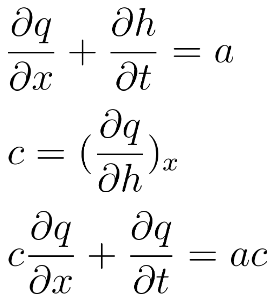

this is the surface slope as a function of (x, t) downhill in x direction beta is the slope of inclination


$$\[ \alpha = \beta - \frac{\partial{h}}{\partial{x}} \]$$


the paper also defines a value for u- this value is based on a  pre established tou value of rho*g*sin(alpha)


$$\[ u = \frac{\rho g h sin(\alpha)} {A}^{m} \]$$


where rho is density, h is height, g is gravity and alpha is the same as defined above.

the paper also defines at a(x,t) based on seaonal and or climate driven accumulation


$$\[ a(x,t) = a_0(x) + a_1(x,t) \]$$


they go on to say that a0 will be the avergaed rate of accumulation over a full year(net accumulation) and a1 will be the departure from a0(produced by seaonal or climatic changes

#### Describe all terms and parameters. 

q = volume of ice passing a given point in unit time (1 / unit breadth)

a = accumulation rate at surface (positive = addition of ice due to snowfall or avalanche, negative = melting or evaporation of ice)

c = velocity (but not velocity of the ice itself, which is u = q/h)

#### Describe any assumptions being made

We assume the volume and velocity (c) of the glacier are constant. Some simulations run assume accumulation is constant, and some assume accumulation oscillates a sine function throughout the year.

## Numerical Methods

#### Describe the numerical methods used.

Forward Euler

#### Why did you choose to use these methods

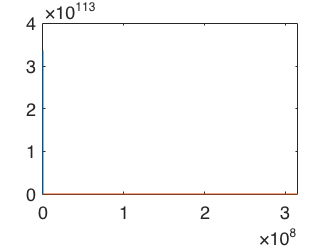

% Forward Euler
%oarameters
rho = 917;% ice density kg/m^3
g = 9.81;             % gravity (m/yr^2)
m = 3;                % constant from autumns last paper
A = 7*10^6;          % basal roughness, ask for value
beta = 1.5*10^-3;   %slope
alpha = beta;%bed slope--> 
% we assume that spoacial chanhges negligable

%time
year = 24*365*60*60; %year in seconds
month = year/12;%month in seconds
day = year/365;
tf = 10*year; %time frame and also time final running 10 years
dt = day; %time step in months
nt = tf/dt; %number of time steps
t = linspace(0,tf,nt);

%grid spacing
dx = 100; %meters, size of grid step
glacier_length = 10000; %length of our mountain glacier
x = linspace(0, glacier_length,dx);
nx = length(x);

%H initial!
h_init = 70; %m
H = nan(nx,nt);
H(:,1) = h_init;

%Accumulation rate


for k = 1:nt-1
    %calulating U for each time step
    u = ((rho.*g.*H(:,k).*alpha).^m)./A;
    %setting up the M matrix
    M = spdiags([u*dt/dx.*ones(nx,1),u*dt/dx.*ones(nx,1)],-1:0,nx,nx);

    %boundary conditions
    %height goes to 0 at the end of the glacier
    %we need an initial condition
    M(end,end) = 0;
    M(end,end-1) = 0;
    %set u value each time from last u value calculated

    H(:,k+1) = M*H(:,k);
    %-a*v*dt
end

plot(t, H)

%plotting results
%we want to 

% %bouyndart conditions
% %we know height goes to 0 at the end
% %we know 70 is our initial height value
% M(1,1) = 1;
% M(1,2) = 0;
% M(2,1) = 1;
% M(2,2) = 1-Cor;
% 
% % grid creation
% 
% %need to define dy i dont know how to incorperate the courant number into
% %this ?
% %our matrix used corant number but how do we deal with this with a changing
% %velocity??
% 
% 
% %a = sin(2*pi*x_gl);
% 
% 
% 
% H = nan(nx,nt);
% 
% H(:,1) = H_t0;
% 
% M = spdiags([u*dt/du.*ones(nx,1),u*dt/du.*ones(nx,1)],-1:0,nx,nx);% can i use this same matrix stucture
% 
% M(1,1) = 1;
% M(1,2) = 0;
% M(2,1) = 1;
% M(2,2) = 1-Cor;
% 
% %boundary
% 
% 
% out = 'done'
% figure
% plot(x_gl,H(:,1:36.5:end),'.')%ploting for each month
% xlabel('x(m)')
% ylabel('height of glacier')
% title('Advection using C = 1')


## Results

#### What simulations did you run with the model?

Changed accumulation from constant to sin function (seasonal changes)

#### Describe the results.

#### How do the results compare with any known solutions, or data?

#### How do the results change with different methods, time steps, grid spacing, or model parameters?

#### What did the model tell you about the process you were studying?

#### How could the model be improved in terms of methods used or processes included?